## Reduced Order Modeling (ROM)

Model order reduction is a family of methods for creating surrogate models of large-scale systems. This interactive notebook introduces the Reduced Basis (RB) method a ROM technique with a strong mathematical ground that can be used to approximate solutions to Partial Differential Equations (PDEs) for real-time or multi-query applications. The RB method is used in this work to obtain a low-rank elasticity model to be used in a Digital Twin for real-time structural analysis.

**Note: **No third-party packages are needed for this script. Originally created on MATLAB 2022b

%% PROJECT CONFIGURATION %%
% Dependencies
addpath("include\")
% Parameters:
dir_model    = './../examples/Ex1_compliant_joint';      % Path to nodes and elements files.
dir_fea_data = './../examples/Ex1_compliant_joint/data'; % Path to high-fidelity simulation samples (snapshots).
partition_ratio = 0.2;      % Ratio of samples to be used in the rom
 

The main principle of the RB method is to divide the computational work into two stages:

- **Offline Stage - **It is the most intensive part of the method. It starts by parameterizing a system. Then by collecting snapshots of the system  on different states using a high-fidelity simulator. Finally, a set of basis and parameter reconstruction policies are determined in a systematic way.

- **Online Stage - **

## Offline Stage

### Import Model's Data

The RB method is a data-driven framework. 

% Import data
[ Nodes, ...            % Model's nodes in matrix format
  Elements, ...         % Model's elementes in matrix format
  CVonMises, ...        % Collection of VonMises snapshots (100%)
  CDisplacementX, ...   % Collection of x-displacement snapshots (100%)
  CDisplacementY, ...   % Collection of y-displacement snapshots (100%)
  CDisplacementZ, ...   % Collection of z-displacement snapshots (100%)
  CInputs, ...          % Collection of input parameters (100%)
  TrainSet, ...         % Set of index for offline stage (ratio)
  ValSet ...            % Set of index for online validation (1-ration)
] = import_data( dir_model, dir_fea_data, partition_ratio );

% Slice training data
DisplacementX = CDisplacementX(:,TrainSet); % x-displacement
DisplacementY = CDisplacementY(:,TrainSet); % y-displacement
DisplacementZ = CDisplacementZ(:,TrainSet); % z-displacement
VonMises      = CVonMises(:,TrainSet);      % VonMises
u = CInputs(:,TrainSet);                    % Input parameters


### Model Visualization

idx = 20;
deformation = [ CDisplacementX(:,idx), CDisplacementY(:,idx), CDisplacementZ(:,idx) ];
model_plot( Nodes + deformation', Elements, CVonMises(:,idx) );
title( "u = " + CInputs(idx) + " [mm]", "FontName", "Cambria Math" )

### Proper Orthogonal Decomposition

[Ux,Zx,Vx] = svd( DisplacementX, "econ", "vector" );
[Uy,Zy,Vy] = svd( DisplacementY, "econ", "vector" );
[Uz,Zz,Vz] = svd( DisplacementZ, "econ", "vector" );
[Uv,Zv,Vv] = svd( VonMises, "econ", "vector" );

### Reduced Order Basis (ROB) - Visualization

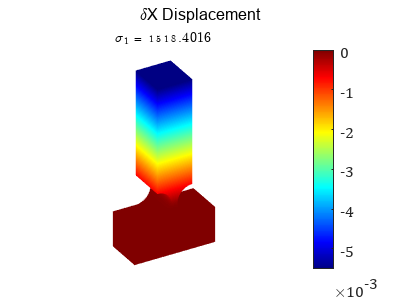

grid_ = [1,1];

plotEigenPortraits( Nodes, Elements, Ux, Zx, grid_, [-30, 30] );
sgtitle( '\deltaX Displacement' )

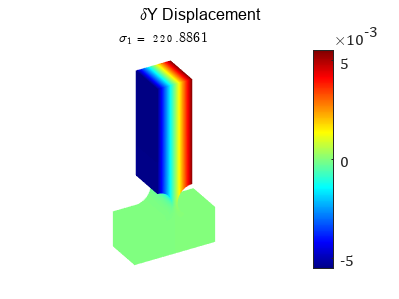


plotEigenPortraits( Nodes, Elements, Uy, Zy, grid_, [-30, 30] );
sgtitle( '\deltaY Displacement' )

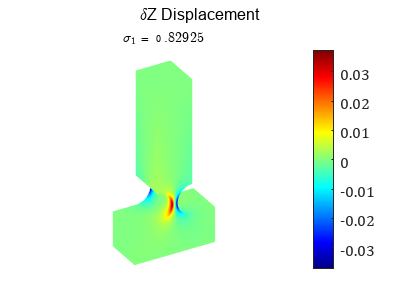


plotEigenPortraits( Nodes, Elements, Uz, Zz, grid_, [-30, 30] );
sgtitle( '\deltaZ Displacement' )

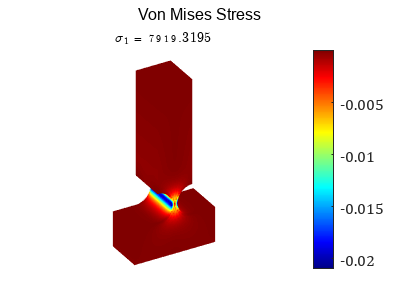


plotEigenPortraits( Nodes, Elements, Uv, Zv, grid_, [-30, 30] );
sgtitle( 'Von Mises Stress' )

### ROB - Error Estimation

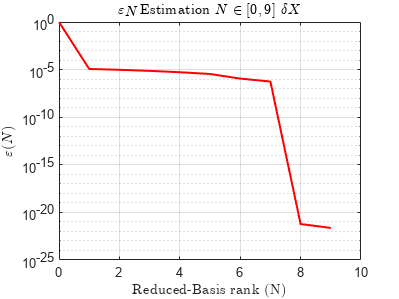

errorEstimationPlot( Zx, "$\delta X$" )

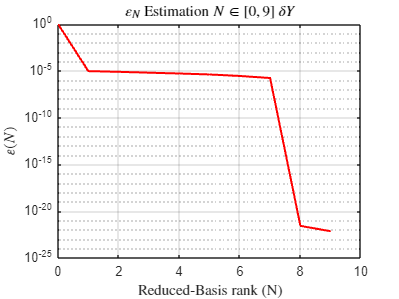

errorEstimationPlot( Zy, "$\delta Y$" )

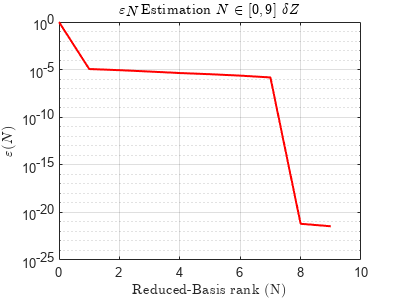

errorEstimationPlot( Zz, "$\delta Z$" )

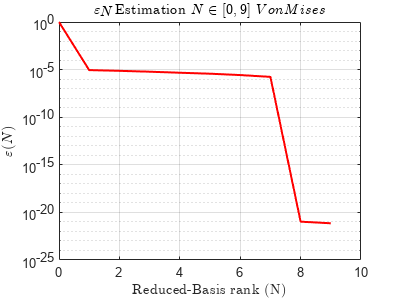

errorEstimationPlot( Zv, "$VonMises$" )


n_basis = length( u );

### Parameter Reconstruction

[Vx_hat] = parameterReconstruction( DisplacementX, Ux, Zx );
[Vy_hat] = parameterReconstruction( DisplacementY, Uy, Zy );
[Vz_hat] = parameterReconstruction( DisplacementZ, Uz, Zz );
[Vv_hat] = parameterReconstruction( VonMises, Uv, Zv );

basis_index = 1;

figure;
hold on;
grid on;

t = -6:0.1:6;
plot_sorted( [u,0], [Vx_hat(basis_index,:),0], ':o' )
plot_sorted( [u,0], [Vy_hat(basis_index,:),0], ':x' )
plot_sorted( [u,0], [Vz_hat(basis_index,:),0], '+-' )
plot_sorted( [u,0], [Vv_hat(basis_index,:),0], ':s' )

title ( "\textbf{Parameter reconstruction} ($\zeta_1$)", "Interpreter", "latex", "FontSize", 16 )
xlabel( "$\mu_i$", "Interpreter", "latex", "FontSize", 14 )
ylabel( "$\phi(\mu_i)$", "Interpreter", "latex", "FontSize", 14 )
xlim( [ min(CInputs), max(CInputs) ] )


### Linear Curve Fit Example

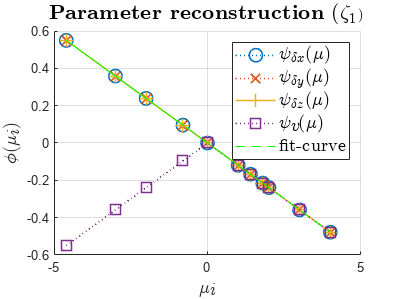

V_hat = Vx_hat;
X = [ ones( size(u,2), 1 ), u' ];
a = X'*X \ X'* V_hat(basis_index,:)';

plot( u, X * a, "--g" )
legend( ["$\psi_{\delta x}(\mu)$", "$\psi_{\delta y}(\mu)$", "$\psi_{\delta z}(\mu)$", "$\psi_{v}(\mu)$", "fit-curve"], "Interpreter", "latex", "FontSize", 14 )

### Save Model

model_name = "Ex1_compliant_joint";
basis = [ Zx(1) * Ux(:,1), Zy(1) * Uy(:,1), Zz(1) * Uz(:,1), Zv(1) * Uv(:,1) ];
dirpath = "dump\" + model_name;
if ~exist(dirpath,'dir'), mkdir(dirpath); end
writematrix( basis, dirpath + "/basis.txt", "Delimiter", "tab" )
writematrix( a', dirpath + "/coefficients.txt", "Delimiter", "tab" )
 

### Load Model

model_name = "Ex1_compliant_joint";
basis = readmatrix( "./dump/" + model_name + "/basis.txt" );
a = readmatrix( "./dump/" + model_name + "/coefficients.txt" );
 

### Model Evaluation

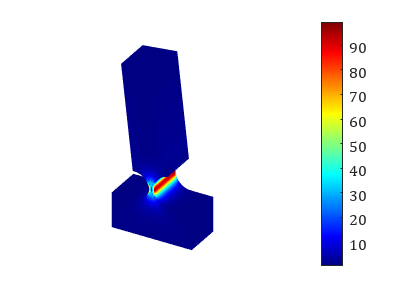

[model] = evalModel( a, basis );
input_parameter = -5;
[ deformation, Dv ] = model( input_parameter );

model_plot( Nodes + deformation', Elements, Dv );

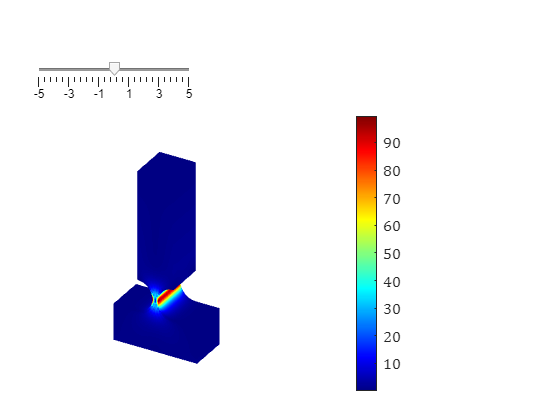

fig = uifigure;
ax = uiaxes(fig, 'DataAspectRatio',[1,1,1], 'Visible','off', 'View', [30,30] );

h = graphic_engine( Nodes, Elements, Dv, ax );
sld = uislider(fig, 'Position',[40 350 150 3], 'ValueChangedFcn', @(sld,event) updateModel( sld.Value, h, Nodes', model ) );

sld.Limits = [-5,5];

### Sanity Check

mu_set = CInputs( ValSet ); n = length( mu_set );
% Error Vectors
e_VonMises = zeros( n, 5 );
e_DisX = zeros( n, 5 );
e_DisY = zeros( n, 5 );
e_DisZ = zeros( n, 5 );

for j = 1 : n
     i = ValSet( j );
     % Reduced-Order Model Evaluation
     [ deformation, Dv ] = model( mu_set( j ) );
     % Full-Order Model Evaluation
     Dv_val = CVonMises(:,i);
     deformation_val = [ CDisplacementX(:,i), CDisplacementY(:,i), CDisplacementZ(:,i) ];
     % Equivalent Stress Relative Error
     e = 100 * abs( Dv - Dv_val ) ./ Dv_val;
     e_VonMises( j, : ) = [ mu_set( j ), mean( e ), max( e ), min( e ), std( e ) ];
     % Deformation Residual
     e = 100 * abs( deformation - deformation_val );
     e_DisX( j, : ) = [ mu_set( j ), mean( e(:,1) ), max( e(:,1) ), min( e(:,1) ), std( e(:,1) ) ];
     e_DisY( j, : ) = [ mu_set( j ), mean( e(:,2) ), max( e(:,2) ), min( e(:,2) ), std( e(:,2) ) ];
     e_DisZ( j, : ) = [ mu_set( j ), mean( e(:,3) ), max( e(:,3) ), min( e(:,3) ), std( e(:,3) ) ];
end

% Equivalent Stress Stats:
e_max_VonMises  = mean( e_VonMises(:,3) );
e_var_VonMises  = mean( e_VonMises(:,5) );
e_mean_VonMises = mean( e_VonMises(:,2) );

% X-displacement Stats:
e_max_DisX      = mean( e_DisX(:,3) );
e_var_DisX      = mean( e_DisX(:,5) );
e_mean_DisX     = mean( e_DisX(:,2) );

% Y-displacement Stats:
e_max_DisY      = mean( e_DisY(:,3) );
e_var_DisY      = mean( e_DisY(:,5) );
e_mean_DisY     = mean( e_DisY(:,2) );

% Z-displacement Stats:
e_max_DisZ      = mean( e_DisZ(:,3) );
e_var_DisZ      = mean( e_DisZ(:,5) );
e_mean_DisZ     = mean( e_DisZ(:,2) );

Name = [ "VonMises [%]", "x-displacement [mm]", "y-displacement [mm]", "z-displacement [mm]" ]';
Max  = [ e_max_VonMises, e_max_DisX, e_max_DisY, e_max_DisZ ]';
Var  = [ e_var_VonMises, e_var_DisX, e_var_DisY, e_var_DisZ ]';
Mean = [ e_mean_VonMises, e_mean_DisX, e_mean_DisY, e_mean_DisZ ]';

table( Name, Max, Var, Mean, 'VariableNames', ["Name", "Max", "Std. d.", "Mean"] )

ans = 4×4 table
            Name                Max         Std. d.         Mean   
    _____________________    __________    __________    __________

    "VonMises [%]"              0.38807     0.0018524     0.0010922
    "x-displacement [mm]"     0.0060479     0.0012482    0.00079694
    "y-displacement [mm]"    0.00062578    0.00013739    9.2375e-05
    "z-displacement [mm]"    3.7637e-05     8.397e-07    2.5079e-07


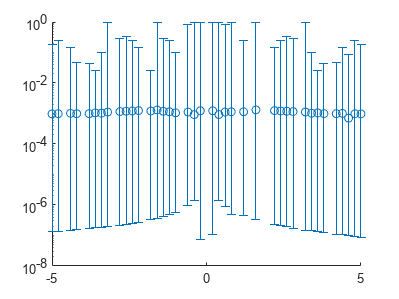


figure;
hold on;
e = e_VonMises;
errorbar( e( :,1 ), e( :,2 ), e( :,4 ) - e( :,2 ) , e( :,2 ) - e(:,3), 'o' )
set( gca, 'YScale', 'log' );